# Exercise 5: Draw Prepared Images

## Plot sample image

Various sample images have already been acquired and processed for you to draw. Load one of them in MATLAB to see what the original image looks like. Start with a drawing of the MathWorks logo.

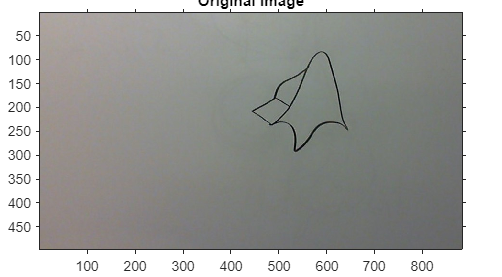

imshow('MathWorksLogo.jpg')
axis on
title('Original Image')

## Load pathways for sample image

In addition to the original image, a MAT-file is provided to you that contains the coordinates of pixels from this image that describe the line traces in the image. Load this data into the workspace.

load MathWorksLogo.mat segmentsPix xLimPix yLimPix
nSegments = length(segmentsPix);

## Plot pixels chosen from sample image

Loop through the cell array `segmentsPix`. From each cell, extract the data, which is a two-column list of pixel coordinates. Plot each coordinate path. Call `hold on` after each `plot` so that the following `plot` command will add to the current plot instead of replacing it.

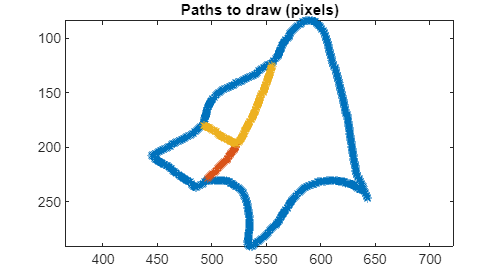

for ii = 1:nSegments
    coords = segmentsPix{ii};
    plot(coords(:,2),coords(:,1),'-*')
    hold on
end
hold off
axis equal ij
title('Paths to draw (pixels)')

## Convert pixel coordinates to physical distances

In order to draw the image on the whiteboard, you'll have to convert the units from pixels to physical distances. In the previous exercise, you identified the limits of the whiteboard in meters. Load these values from the MAT-file `WhiteboardLimits.mat` that you created in the previous exercise.

load WhiteboardLimits.mat xLim yLim

For each point in each line trace, convert the coordinates from pixels to meters using the `transformPixelsToMeters` function. Also, choose what fraction of the total available drawing space you want to use.

fraction = 0.7;
segmentsMeters = transformPixelsToMeters(segmentsPix,xLim,yLim,xLimPix,yLimPix,fraction);

## Explore transformPixelMeter() - Badweh

% inputs
xLim
yLim
xLimPix
yLimPix
fraction


%the ranges xRange, yRange, xRangePix, and yRangePix.
xMinM = xLim(1)
yMinM = yLim(1)
xRangeM = diff(xLim)
yRangeM = diff(yLim)

% Determine the range of the coordinates to draw
xMinPix = xLimPix(1)
yMinPix = yLimPix(1)
xRangePix = diff(xLimPix)
yRangePix = diff(yLimPix)


% Scale from pixels to real world units (meters)
xScaleFactor = fraction * xRangeM/xRangePix
yScaleFactor = fraction * yRangeM/xRangePix


% Pick the smaller scale factor. If both are NaN, pick 0.
pix2M = min(xScaleFactor,yScaleFactor)
if isnan(pix2M)
    pix2M = 0;
end

% Identify the origin of the scaled drawing
centerMeters = [xMinM yMinM] + [xRangeM yRangeM]/2
drawingOriginM = centerMeters - pix2M*[xRangePix yRangePix]/2

segmentsMeters = cell(size(segmentsPix))
nSegments = length(segmentsPix)





coordsPix = segmentsPix{1}

coordsPix =    247   643
   246   643
   245   642
   244   642
   243   641
   242   641
   241   640
   240   639
   239   638
   238   639


coordsPix1 = fliplr(coordsPix) %Convert from row,col to x,y

coordsPix1 =    643   247
   643   246
   642   245
   642   244
   641   243
   641   242
   640   241
   639   240
   638   239
   639   238


coordsMeters = pix2M*(coordsPix1-[xMinPix yMinPix]) + drawingOriginM

Unrecognized function or variable 'pix2M'.

segmentsMeters{1} = coordsMeters




for ii = 1:nSegments
    xy = segmentsMeters{1};
    plot(xy(:,1),xy(:,2),'-*')
    hold on
end
hold off
axis equal ij
title('Paths to draw (meters)')



## Plot paths in meters

Just as you plotted the line traces when they were defined in pixel coordinates, now plot the line traces defined in meters. The plot should look the same as before. However, now the units on the x and y axes should be different, and they should be bounded within the limits of the drawable area as defined by `xLim` and `yLim`.

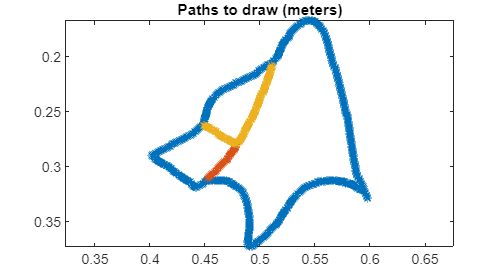

for ii = 1:nSegments
    xy = segmentsMeters{ii};
    plot(xy(:,1),xy(:,2),'-*')
    hold on
end
hold off
axis equal ij
title('Paths to draw (meters)')

## Reduce size of each segment

At this point, each segment may be composed of a large number of points that are very close to each other. It would be sluggish to try to draw all of the points we have defined. Instead, you can define the segment with a smaller number of points that still roughly define the same path. Specify a minimum distance between two consecutive points and then remove points from each segment such that all the points are at least that far apart. Here, we're using 2 mm (0.002 m) as the minimum distance, but you can modify this depending on how detailed your drawing is.

radius = 0.002; %Max distance between points to draw (meters)
for ii = 1:nSegments
    segmentsMeters{ii} = reduceSegment(segmentsMeters{ii},radius);
end

% norm(segment(test,:) - segment(reference,:))

## Plot reduced paths in meters

Plot the line traces one more time to observe the reduction of data and verify that the path still looks like the original drawing.

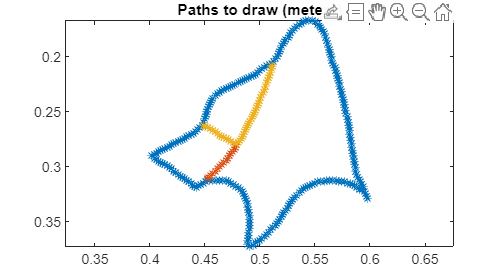

for ii = 1:nSegments
    xy = segmentsMeters{ii};
    plot(xy(:,1),xy(:,2),'-*')
    hold on
end
hold off
axis equal ij
title('Paths to draw (meters)')

Note: If the shape looks drastically different from the above plot, decreasing the radius value and repeating the last two sections can help retain more features from the original drawing.

## Identify initial position in Z

Hang the robot on the whiteboard. Measure the initial string lengths L_i. Execute this section of code, and enter these lengths in the dialog box.

Z_i = initialPosition();

## Convert distances to angular displacements

Use the `xyToRadians` function created in a previous exercise to convert each coordinate trace from units of meters to angular positions. Store this new set of line traces in a new variable `segmentsTheta`.

load RobotGeometry.mat Base
segmentsTheta = cell(size(segmentsMeters));
for ii = 1:nSegments
    segmentsTheta{ii} = xyToRadians(segmentsMeters{ii},Z_i,Base);
end

## Connect to hardware

Connect to the Arduino hardware and peripherals as you have done in previous exercises.

a = arduino;
carrier = motorCarrier(a);
s = servo(carrier,3);
pidML = pidMotor(carrier,2,'position',3,[0.18 0.0 0.01]); % Modify the PID gains [Kp Ki Kd] as per your requirements
pidMR = pidMotor(carrier,1,'position',3,[0.18 0.0 0.01]); % Modify the PID gains [Kp Ki Kd] as per your requirements

Load the servo position values. Raise both markers.

load ServoPositions.mat LeftMarker RightMarker NoMarker
writePosition(s,NoMarker)

## Draw image on whiteboard

In a loop, draw each of the line traces stored in the `segmentsTheta` variable. Each cell in the variable corresponds to a line trace. For each trace, extract the angular position data. Then move the robot to the first position, lower the marker, and draw all points in that trace. Finally, raise the marker before proceeding to draw the next segment.

for ii = 1:nSegments
    % Get theta for current segment
    thetaList = segmentsTheta{ii};
    % Move to first position and lower marker
    moveToRadians(thetaList(1,:),pidML,pidMR)
    writePosition(s,LeftMarker)
    % Move to all positions of current segment
    moveToRadians(thetaList,pidML,pidMR)
    % Raise marker
    writePosition(s,NoMarker)
end

Clear hardware variables when you're done using them.

clear a carrier s pidML pidMR

*Copyright 2018 - 2020 The MathWorks, Inc.*